# Continuously Generate WINNER II Channel Coefficients

Continuously generate channel coefficients for each link in a two-link system layout.

Configure model parameters.


cfgWim = winner2.wimparset;
cfgWim.SampleDensity = 20;
cfgWim.RandomSeed = 10; % For repeatability

Configure layout parameters.

BSAA  = winner2.AntennaArray('UCA',8,0.02);  % UCA-8 array for BS
MSAA1 = winner2.AntennaArray('ULA',2,0.01);  % ULA-2 array for MS1
MSAA2 = winner2.AntennaArray('ULA',4,0.005); % ULA-4 array for MS2
MSIdx = [2,3];
BSIdx = {1};
NL = 2;
rndSeed = 5;
cfgLayout = winner2.layoutparset(MSIdx,BSIdx,NL,[BSAA,MSAA1,MSAA2],[],rndSeed);

Generate channel coefficients for the first time.

[H1,~,finalCond] = winner2.wim(cfgWim,cfgLayout);


Generate a second set of channel coefficients.

[H2,~,finalCond] = winner2.wim(cfgWim,cfgLayout,finalCond);


Concatenate H1 and H2 in time domain.

H = cellfun(@(x,y) cat(4,x,y),H1,H2,'UniformOutput',false);


Plot H for the first link, 1st Tx, 1st Rx, and 1st path. The plot shows the channel continuity over the two outputs from the `winner2.wim` function.

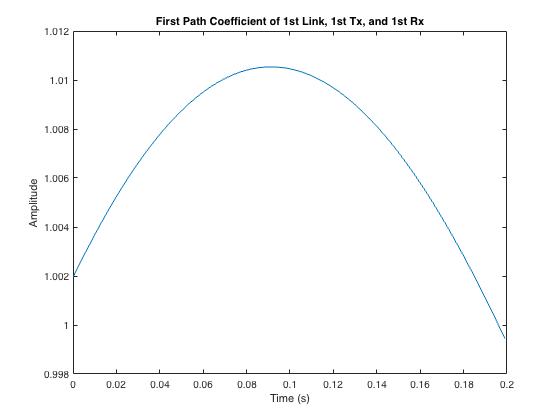

figure;
Ts = finalCond.delta_t(1);  % Sample time for the 1st link
plot(Ts*(0:2*cfgWim.NumTimeSamples-1)', ...
    abs(squeeze(H{1}(1,1,1,:))));
xlabel('Time (s)');
ylabel('Amplitude');
title('First Path Coefficient of 1st Link, 1st Tx, and 1st Rx');

*Copyright 2018 The MathWorks, Inc.*